load("test2Data.mat")

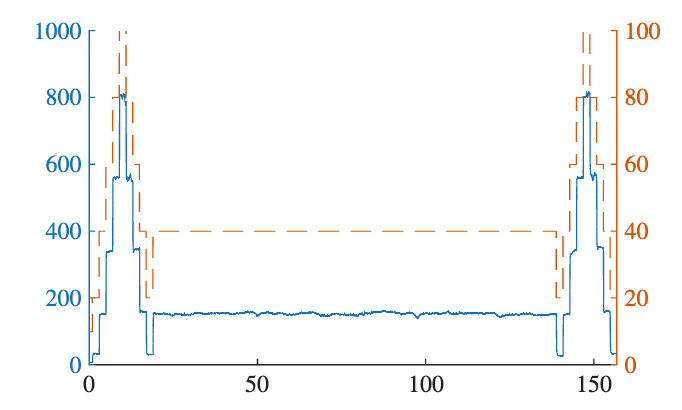

figure, clf, hold on
yyaxis left
plot(rawTime, rawThrust)
yyaxis right
plot(rawTime, rawThrottle, "--")
ylim([0 100])
hold off

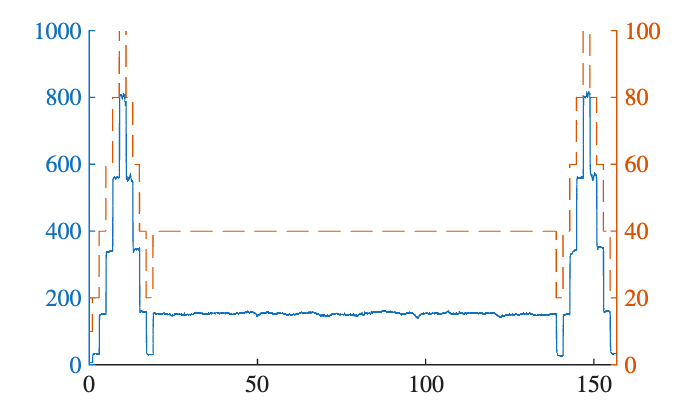


[thrust,time] = resample(rawThrust, rawTime, 80);

throttle = zeros(length(time),1);
throttle(1:235) = 20;
throttle(236:396) = 40;
throttle(397:555) = 60;
throttle(556:715) = 80;
throttle(716:875) = 100;
throttle(876:1035) = 80;
throttle(1036:1194) = 60;
throttle(1195:1354) = 40;
throttle(1355:1515) = 20;
throttle(1516:11104) = 40;
throttle(11105:11265) = 20;
throttle(11266:11425) = 40;
throttle(11426:11584) = 60;
throttle(11585:11745) = 80;
throttle(11746:11905) = 100;
throttle(11906:12064) = 80;
throttle(12065:12224) = 60;
throttle(12225:12384) = 40;
throttle(12385:end) = 20;

figure, clf, hold on
yyaxis left
plot(rawTime, rawThrust)
yyaxis right
plot(rawTime, rawThrottle, "--")
plot(time, throttle, "--")
ylim([0 100])
hold off

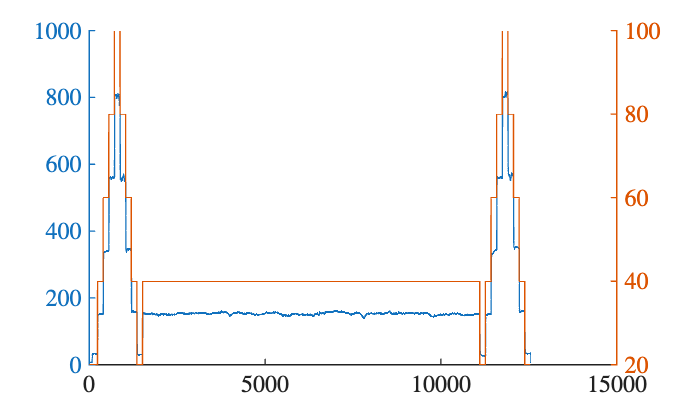


figure, clf, hold on
yyaxis left
plot(thrust)
yyaxis right
plot(throttle)
hold off


% 20-40
data = iddata(thrust(200:300)-thrust(200),throttle(200:300)-throttle(200),1/80)

data = Time domain data set with 101 samples.
Sample time: 0.0125 seconds           
                                      
Outputs      Unit (if specified)      
   y1                                 
                                      
Inputs       Unit (if specified)      
   u1                                 
                                      
Data Properties

C20_40 = procest(data,'P1D')


C20_40 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 5.9271                  
       Tp1 = 0.028221                
        Td = 0.044725                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 97.78%                     
FPE: 1.687, MSE: 1.59                              
 
Model Properties


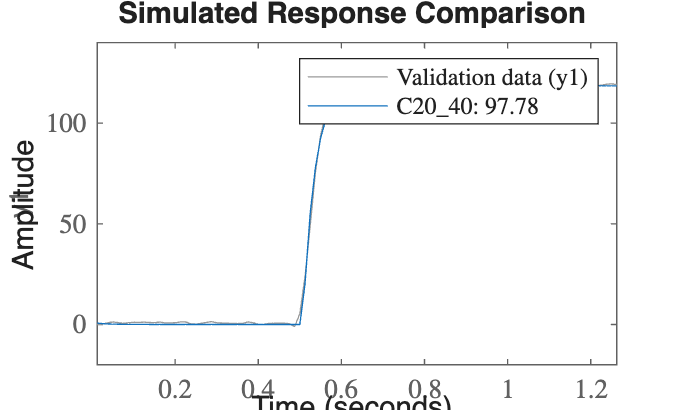

compare(C20_40,data);


% 40-60
data = iddata(thrust(360:460)-thrust(360),throttle(360:460)-throttle(360),1/80);
C40_60 = procest(data,'P1D')


C40_60 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 9.2674                  
       Tp1 = 0.027728                
        Td = 0.02925                 
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 97.85%                     
FPE: 3.917, MSE: 3.691                             
 
Model Properties


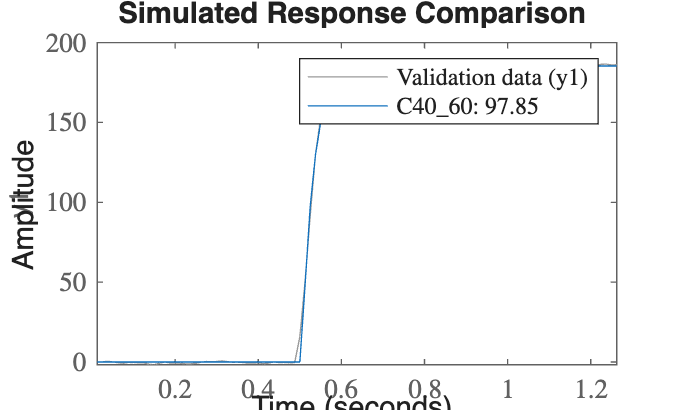

compare(C40_60,data);


% 60-80
data = iddata(thrust(520:620)-thrust(520),throttle(520:620)-throttle(520),1/80);
C60_80 = procest(data,'P1D')


C60_80 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 10.985                  
       Tp1 = 0.025555                
        Td = 0.042925                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 97.74%                     
FPE: 6.082, MSE: 5.731                             
 
Model Properties


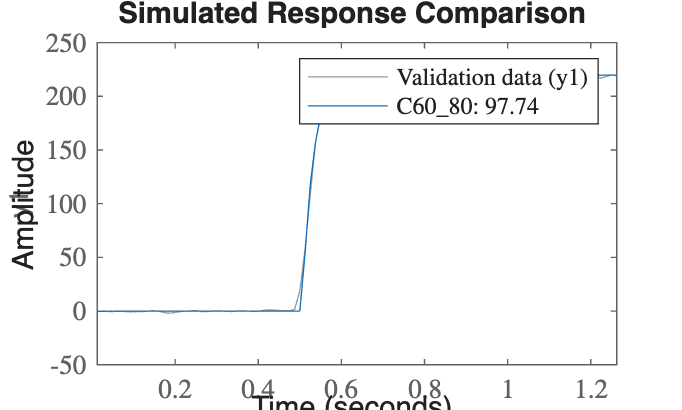

compare(C60_80,data);


% 80-100
data = iddata(thrust(680:780)-thrust(680),throttle(680:780)-throttle(680),1/80);
C80_100 = procest(data,'P1D')


C80_100 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 12.333                  
       Tp1 = 0.0269                  
        Td = 0.035075                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 96.85%                     
FPE: 14.87, MSE: 14.01                             
 
<a href="matlab:if exist('C80_100','var'), if isa(C80_100,'idproc'), disp(' '); disp(get(C80_100)), else disp(' '); disp('Unable to display properties for variable C80_100 because it is no longer a/an idproc object.');, end, else matlab.graphics.internal.getForDisplay('C80_100'), end">Model Properties<

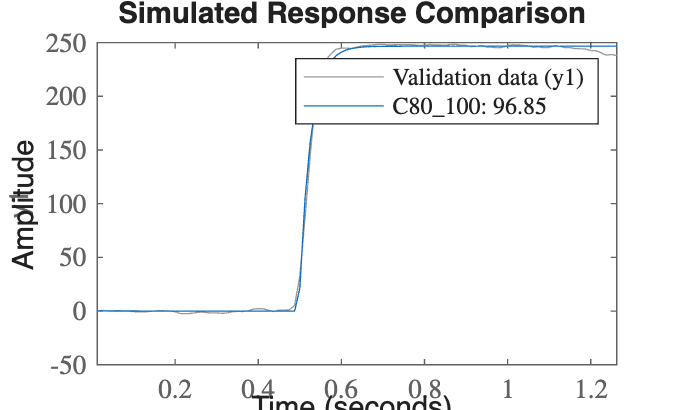

compare(C80_100,data);


% 100-80
data = iddata(thrust(860:940)-thrust(860),throttle(860:940)-throttle(860),1/80);
C100_80 = procest(data,'P1D')


C100_80 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 11.098                  
       Tp1 = 0.026844                
        Td = 0.033588                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 94.86%                     
FPE: 26.93, MSE: 25.01                             
 
<a href="matlab:if exist('C100_80','var'), if isa(C100_80,'idproc'), disp(' '); disp(get(C100_80)), else disp(' '); disp('Unable to display properties for variable C100_80 because it is no longer a/an idproc object.');, end, else matlab.graphics.internal.getForDisplay('C100_80'), end">Model Properties<

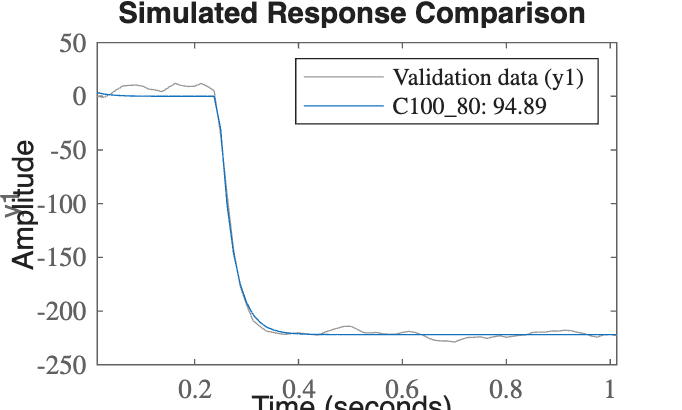

compare(C100_80,data);


% 80-60
data = iddata(thrust(1000:1100)-thrust(1000),throttle(1000:1100)-throttle(1000),1/80);
C80_60 = procest(data,'P1D')


C80_60 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 10.569                  
       Tp1 = 0.023531                
        Td = 0.0313                  
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 96.16%                     
FPE: 15.66, MSE: 14.75                             
 
Model Properties


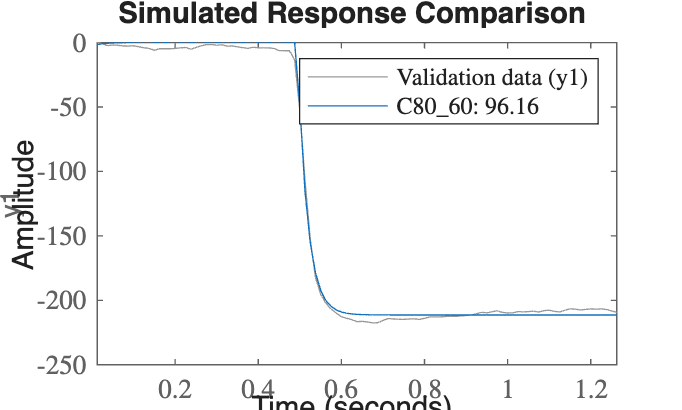

compare(C80_60,data);


% 60-40
data = iddata(thrust(1160:1260)-thrust(1160),throttle(1160:1260)-throttle(1160),1/80);
C60_40 = procest(data,'P1D')


C60_40 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 9.3991                  
       Tp1 = 0.026466                
        Td = 0.046775                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 96.85%                     
FPE: 8.576, MSE: 8.081                             
 
Model Properties


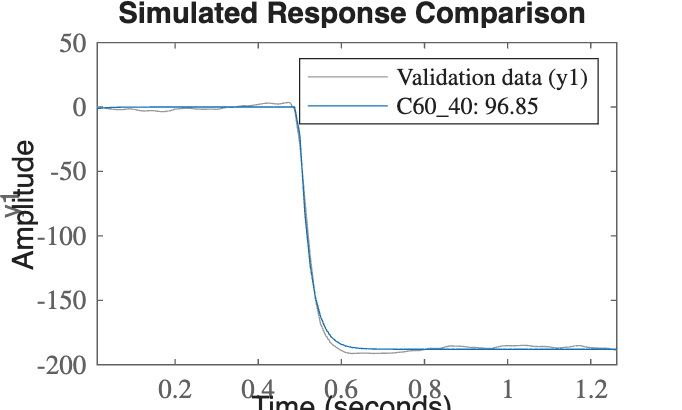

compare(C60_40,data);


% 40-20
data = iddata(thrust(1320:1420)-thrust(1320),throttle(1320:1420)-throttle(1320),1/80);
C40_20 = procest(data,'P1D')


C40_20 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 6.337                   
       Tp1 = 0.045809                
        Td = 0.0442                  
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 98.49%                     
FPE: 0.8865, MSE: 0.8354                           
 
Model Properties


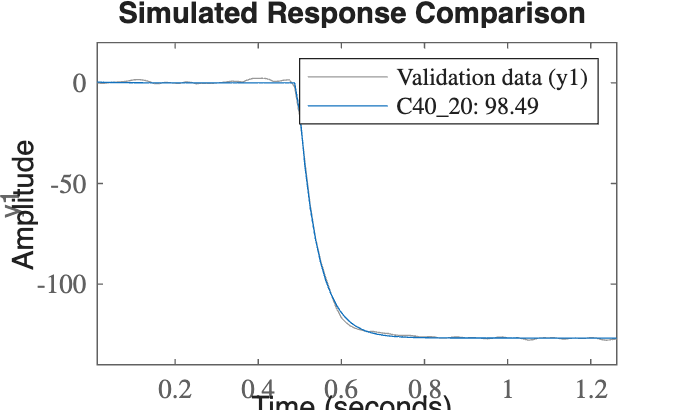

compare(C40_20,data);


% HOT

% 20-40
data = iddata(thrust(11230:11330)-thrust(11230),throttle(11230:11330)-throttle(11230),1/80);
H20_40 = procest(data,'P1D')


H20_40 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 6.1188                  
       Tp1 = 0.036016                
        Td = 0.030625                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 98.02%                     
FPE: 1.439, MSE: 1.356                             
 
Model Properties


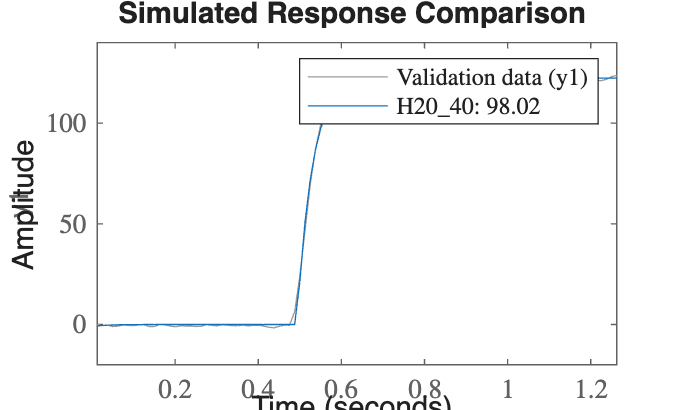

compare(H20_40,data);


% 40-60
data = iddata(thrust(11400:11500)-thrust(11400),throttle(11400:11500)-throttle(11400),1/80);
H40_60 = procest(data,'P1D')


H40_60 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 9.1363                  
       Tp1 = 0.040059                
        Td = 0.023813                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 97.32%                     
FPE: 5.039, MSE: 4.748                             
 
Model Properties


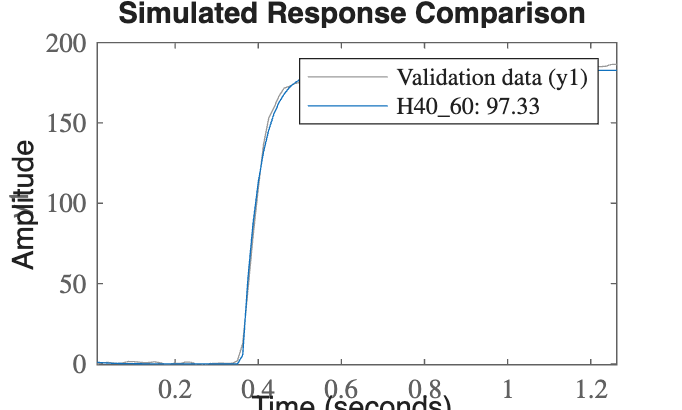

compare(H40_60,data);


% 60-80 HOT
data = iddata(thrust(11560:11660)-thrust(11560),throttle(11560:11660)-throttle(11560),1/80);
H60_80 = procest(data,'P1D')


H60_80 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 10.822                  
       Tp1 = 0.032239                
        Td = 0.043338                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 97.69%                     
FPE: 5.264, MSE: 4.96                              
 
Model Properties


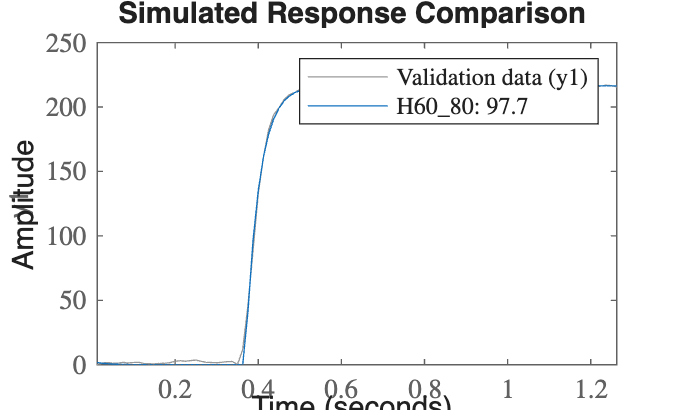

compare(H60_80,data);


% 80-100 HOT
data = iddata(thrust(11720:11820)-thrust(11720),throttle(11720:11820)-throttle(11720),1/80);
H80_100 = procest(data,'P1D')


H80_100 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 12.004                  
       Tp1 = 0.022571                
        Td = 0.030163                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 96.73%                     
FPE: 13.33, MSE: 12.56                             
 
<a href="matlab:if exist('H80_100','var'), if isa(H80_100,'idproc'), disp(' '); disp(get(H80_100)), else disp(' '); disp('Unable to display properties for variable H80_100 because it is no longer a/an idproc object.');, end, else matlab.graphics.internal.getForDisplay('H80_100'), end">Model Properties<

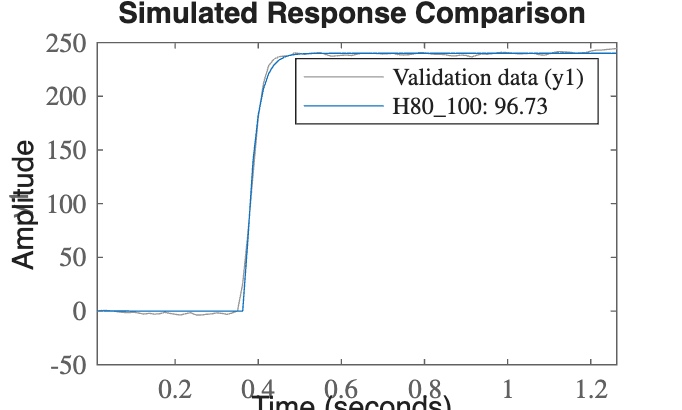

compare(H80_100,data);


% 100-80
data = iddata(thrust(11880:11980)-thrust(11880),throttle(11880:11980)-throttle(11880),1/80);
H100_80 = procest(data,'P1D')


H100_80 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 12.424                  
       Tp1 = 0.035515                
        Td = 0.0172                  
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 94.5%                      
FPE: 38.91, MSE: 36.66                             
 
<a href="matlab:if exist('H100_80','var'), if isa(H100_80,'idproc'), disp(' '); disp(get(H100_80)), else disp(' '); disp('Unable to display properties for variable H100_80 because it is no longer a/an idproc object.');, end, else matlab.graphics.internal.getForDisplay('H100_80'), end">Model Properties<

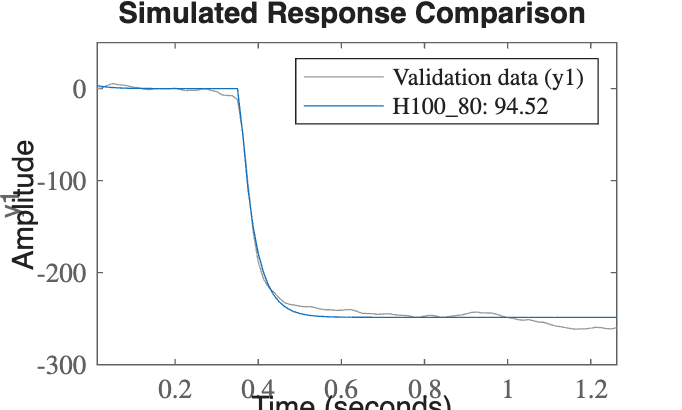

compare(H100_80,data);


% 80-60 HOT
data = iddata(thrust(12030:12130)-thrust(12030),throttle(12030:12130)-throttle(12030),1/80);
H80_60 = procest(data,'P1D')


H80_60 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 11.059                  
       Tp1 = 0.026708                
        Td = 0.030975                
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 95.75%                     
FPE: 20.53, MSE: 19.35                             
 
Model Properties


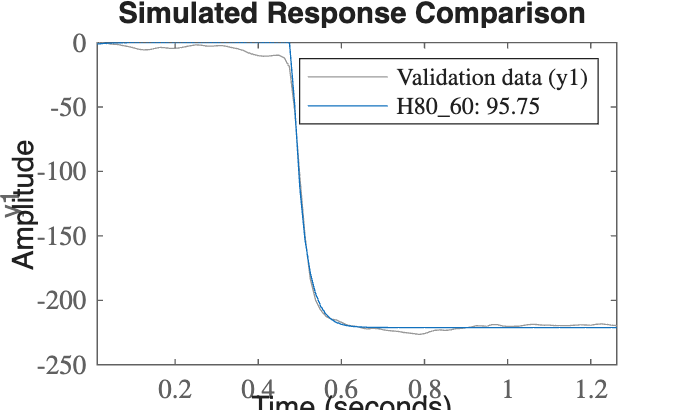

compare(H80_60,data);


% 60-40 HOT
data = iddata(thrust(12190:12290)-thrust(12190),throttle(12190:12290)-throttle(12190),1/80);
H60_40 = procest(data,'P1D')


H60_40 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 9.6615                  
       Tp1 = 0.029354                
        Td = 0.03475                 
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 97.16%                     
FPE: 7.253, MSE: 6.834                             
 
Model Properties


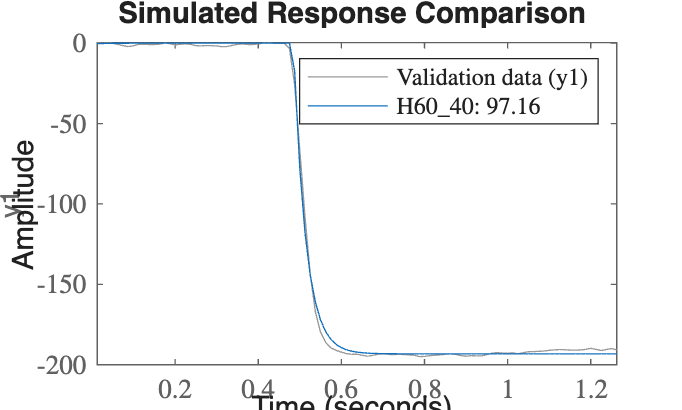

compare(H60_40,data);


% 40-20 HOT
data = iddata(thrust(12350:12450)-thrust(12350),throttle(12350:12450)-throttle(12350),1/80);
H40_20 = procest(data,'P1D')


H40_20 =
 
Process model with transfer function:
             Kp                      
  G(s) = ---------- * exp(-Td*s)     
          1+Tp1*s                    
                                     
        Kp = 6.3286                  
       Tp1 = 0.057171                
        Td = 0.02865                 
                                     
Parameterization:
    {'P1D'}
   Number of free coefficients: 3
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using PROCEST on time domain data "data".
Fit to estimation data: 97.35%                     
FPE: 2.581, MSE: 2.432                             
 
Model Properties


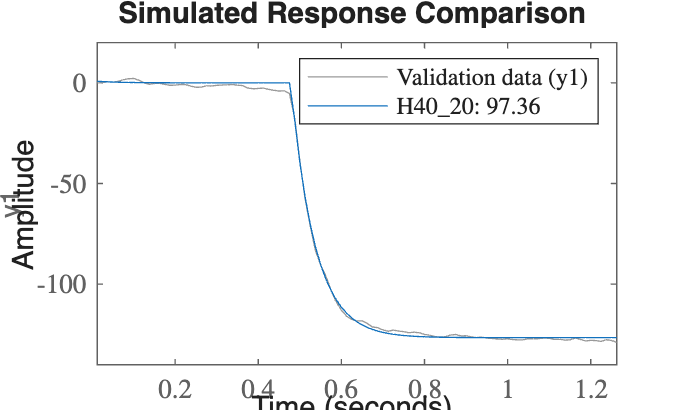

compare(H40_20,data);

Kp_c_2 = [C20_40.Kp C40_20.Kp C40_60.Kp C60_40.Kp C60_80.Kp C80_60.Kp C80_100.Kp C100_80.Kp];
Kp_h_2 = [H20_40.Kp H40_20.Kp H40_60.Kp H60_40.Kp H60_80.Kp H80_60.Kp H80_100.Kp H100_80.Kp];

array2table([Kp_c_1;Kp_h_1],"VariableNames",{'20-40', '40-20', '40-60', '60-40', '60-80', '80-60', '80-100', '100-80'}, "RowNames", {'Cold', 'Hot'})

ans = 2×8 table
            20-40     40-20     40-60     60-40     60-80     80-60     80-100    100-80
            ______    ______    ______    ______    ______    ______    ______    ______

    Cold    6.1971    6.0468    9.5319    10.077    11.216    10.667    12.444    10.742
    Hot     6.1468    6.0384     9.255    9.3521    11.506    10.227    11.142    11.834



Tp_c_2 = [C20_40.Tp1 C40_20.Tp1 C40_60.Tp1 C60_40.Tp1 C60_80.Tp1 C80_60.Tp1 C80_100.Tp1 C100_80.Tp1];
Tp_h_2 = [H20_40.Tp1 H40_20.Tp1 H40_60.Tp1 H60_40.Tp1 H60_80.Tp1 H80_60.Tp1 H80_100.Tp1 H100_80.Tp1];

array2table([Tp_c_1;Tp_h_1],"VariableNames",{'20-40', '40-20', '40-60', '60-40', '60-80', '80-60', '80-100', '100-80'}, "RowNames", {'Cold', 'Hot'})

ans = 2×8 table
             20-40       40-20       40-60       60-40       60-80       80-60       80-100     100-80 
            ________    ________    ________    ________    ________    ________    ________    _______

    Cold    0.029167    0.047377    0.029859    0.029626    0.030443    0.025293     0.03227    0.03294
    Hot     0.035212    0.043944       0.038    0.029245    0.038976      0.0252    0.029284    0.02804



Td_c_2 = [C20_40.Td C40_20.Td C40_60.Td C60_40.Td C60_80.Td C80_60.Td C80_100.Td C100_80.Td];
Td_h_2 = [H20_40.Td H40_20.Td H40_60.Td H60_40.Td H60_80.Td H80_60.Td H80_100.Td H100_80.Td];

array2table([Td_c_1; Td_h_1],"VariableNames",{'20-40', '40-20', '40-60', '60-40', '60-80', '80-60', '80-100', '100-80'}, "RowNames", {'Cold', 'Hot'})

ans = 2×8 table
             20-40      40-20       40-60       60-40       60-80       80-60       80-100      100-80 
            _______    ________    ________    ________    ________    ________    ________    ________

    Cold    0.04445    0.030238    0.030588    0.034275    0.043375     0.01965    0.034425      0.0205
    Hot     0.03155    0.033837    0.029063     0.03605    0.028763    0.019763    0.023425    0.018675
